# **Question-3)**

clc;
clear;

### Defining system dynamics

A = [0, 1, 0;
     8.75*10^4, 0, 7*10^4;
     0, -1.25, -597.82];
B = [0;
     0;
     271.74];
n = length(A);
C = eye(n);
D = zeros([n,1]);

### **(a) Stability check; when position is penalized along with the control input - **

Q = [1, 0, 0; % Assuming a numerical value for q11(=1)
     0, 0, 0;
     0, 0, 0];
R = [1];

fprintf('Rank of observability matrix = %d',rank(obsv(A,Q)))

Rank of observability matrix = 3

fprintf('Rank of controllability matrix = %d',rank(ctrb(A,B))) ;

Rank of controllability matrix = 3

Rank of the observability matrix is equal to the number of states, which means the system is *observable* and hence *detectable*.  

Rank of the controllability matrix is equal to the number of states, which means the system is *controllable* and hence *stabilizable*.  

### **(b) Comparision between different values of q11 in {0.001,0.01,0.1,1,10,100,1000} -**

tspan = 0:0.0005:0.03; % time period is 0.03 seconds
x0 = [0.1; 0; 0]';
Q = [0, 0, 0; 
     0, 0, 0;
     0, 0, 0];
q11 = [0.001,0.01,0.1,1,10,100,1000];

#### X plot

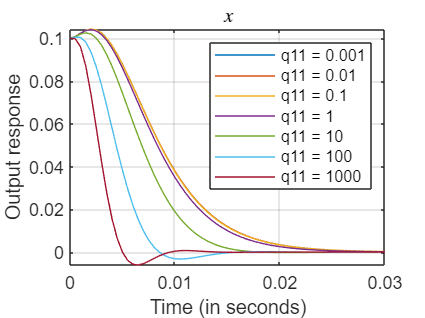

for i = 1:length(q11)
    Q(1,1) = q11(i);
    K = lqr(A, B, Q, R);
    sys = ss(A-B*K,B,C,D); % closed loop-system
    [y, tspan, x] = initial(sys, x0, tspan);
    figure(1)
    plot(tspan,y(:,1))
    title('\textbf{${x}$}','Interpreter','latex');
    xlabel('Time (in seconds)');
    ylabel('Output response');
    hold on
    grid
end 
hold off
legend('q11 = 0.001','q11 = 0.01','q11 = 0.1','q11 = 1','q11 = 10','q11 = 100','q11 = 1000', location='northeast')

#### Xdot plot

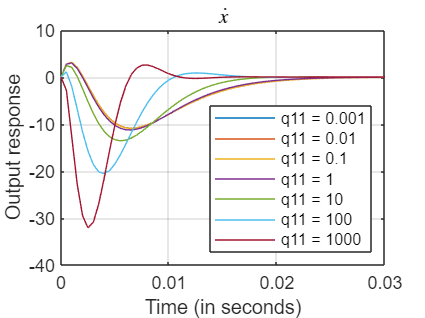

for i = 1:length(q11)
    Q(1,1) = q11(i);
    K = lqr(A, B, Q, R);
    sys = ss(A-B*K,B,C,D); % closed loop-system
    [y, tspan, x] = initial(sys, x0, tspan);
    figure(2)
    plot(tspan,y(:,2))
    title('\textbf{$\dot{x}$}','Interpreter','latex');
    xlabel('Time (in seconds)');
    ylabel('Output response');
    hold on
    grid
end 
hold off
legend('q11 = 0.001','q11 = 0.01','q11 = 0.1','q11 = 1','q11 = 10','q11 = 100','q11 = 1000', location='southeast')

#### Ic plot

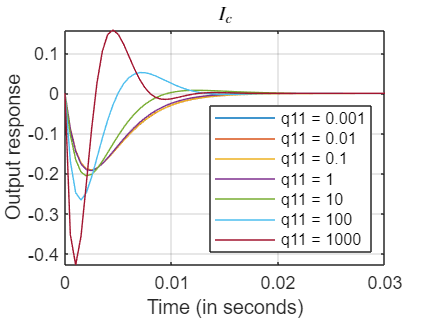

for i = 1:length(q11)
    Q(1,1) = q11(i);
    K = lqr(A, B, Q, R);
    sys = ss(A-B*K,B,C,D); % closed loop-system
    [y, tspan, x] = initial(sys, x0, tspan);
    figure(3)
    plot(tspan,y(:,3))
    title('\textbf{${I_c}$}','Interpreter','latex');
    xlabel('Time (in seconds)');
    ylabel('Output response');
    hold on
    grid
end 
hold off
legend('q11 = 0.001','q11 = 0.01','q11 = 0.1','q11 = 1','q11 = 10','q11 = 100','q11 = 1000', location='southeast')

#### Control input (Vc) plot

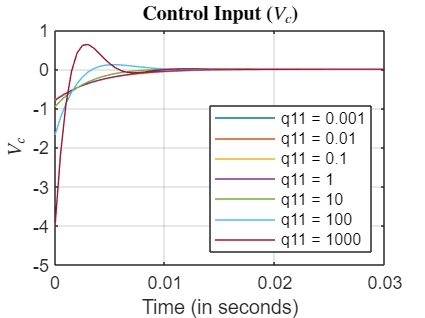

for i = 1:length(q11)
    Q(1,1) = q11(i);
    K = lqr(A, B, Q, R);
    sys = ss(A-B*K,B,C,D); % closed loop-system
    [y, tspan, x] = initial(sys, x0, tspan);
    u = - (K*x')';
    figure(4)
    plot(tspan,u)
    title('\textbf{Control Input (${V_c}$)}', 'Interpreter','latex');
    xlabel('Time (in seconds)');
    ylabel('${V_c}$', 'Interpreter','latex');
    hold on
    grid
end 
hold off
legend('q11 = 0.001','q11 = 0.01','q11 = 0.1','q11 = 1','q11 = 10','q11 = 100','q11 = 1000', location='southeast')

#### Recommended choice of q11 (part-b)

As per the graphs above, it can be seen that as the value of *q11 *increases, the states are stabilized quicker with more changes in less time. For instance, for the value of *q11 equal to 1000, *the states are stabilized faster compared to when the value of *q11 is equal to 0.001. *Also, since the value of the control penalty matrix *R is fixed, *it can be seen that increasing the value of *q11 *leads to higher control input. 

Therefore, if control input is not a concern, then *q11=1000* would be the recommended value in the state penalty matrix. However, if control input is a concern, then choosing *q11=0.001* would be optimal, considering the trade-off would be the time required by the system to stabilize. 

For this problem, assuming both control input and change in states are of interest, I would choose *q11=10,* which gives a good balance between the control input and change in states.

### **(c) RMS Values over a period of 0.1 second for Position and Control Input - **

tspan = 0:0.0005:0.1; % time period is 0.1 seconds
x0 = [0.1; 0; 0]';
Q = [0, 0, 0; 
     0, 0, 0;
     0, 0, 0];
q11 = [0.001,0.01,0.1,1,10,100,1000];

#### RMS plot for position

for i = 1:length(q11)
    Q(1,1) = q11(i);
    K = lqr(A, B, Q, R);
    sys = ss(A-B*K,B,C,D); % closed loop-system
    [y, tspan, x] = initial(sys, x0, tspan);
    figure(5)
    rms_pos = rms(y(:,1));
    semilogx(q11(i),rms_pos,'*', 'MarkerSize',10);
    title('\textbf{RMS Plot for Position}', 'Interpreter','latex');
    xlabel('Values of q11 (in logarithmic scale)');
    ylabel('RMS values');
    fprintf('RMS value of position when q11 is %0.2f = %0.2f \n',q11(i),rms_pos);
    hold on
    grid
end 

RMS value of position when q11 is 0.00 = 0.03 
RMS value of position when q11 is 0.01 = 0.03 
RMS value of position when q11 is 0.10 = 0.03 
RMS value of position when q11 is 1.00 = 0.03 
RMS value of position when q11 is 10.00 = 0.02 
RMS value of position when q11 is 100.00 = 0.02 
RMS value of position when q11 is 1000.00 = 0.02 


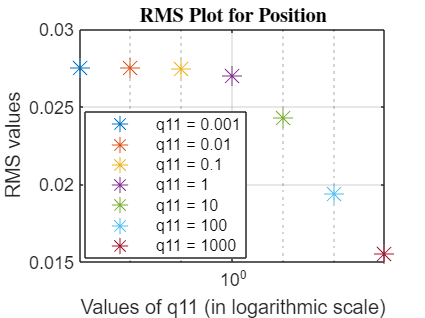

hold off
legend('q11 = 0.001','q11 = 0.01','q11 = 0.1','q11 = 1','q11 = 10','q11 = 100','q11 = 1000', location='best')

#### RMS plot for control input (Vc)

for i = 1:length(q11)
    Q(1,1) = q11(i);
    K = lqr(A, B, Q, R);
    sys = ss(A-B*K,B,C,D); % closed loop-system
    [y, tspan, x] = initial(sys, x0, tspan);
    u = - (K*x')';
    figure(6)
    rms_u = rms(u);
    semilogx(q11(i),rms_u,'*', 'MarkerSize',10);
    title('\textbf{RMS Plot for Control Input (${V_c}$)}', 'Interpreter','latex');
    xlabel('Values of q11 (in logarithmic scale)');
    ylabel('RMS values');
    fprintf('RMS value of control input when q11 is %0.2f = %0.2f \n',q11(i),rms_u);
    hold on
    grid
end 

RMS value of control input when q11 is 0.00 = 0.12 
RMS value of control input when q11 is 0.01 = 0.12 
RMS value of control input when q11 is 0.10 = 0.12 
RMS value of control input when q11 is 1.00 = 0.12 
RMS value of control input when q11 is 10.00 = 0.12 
RMS value of control input when q11 is 100.00 = 0.17 
RMS value of control input when q11 is 1000.00 = 0.34 


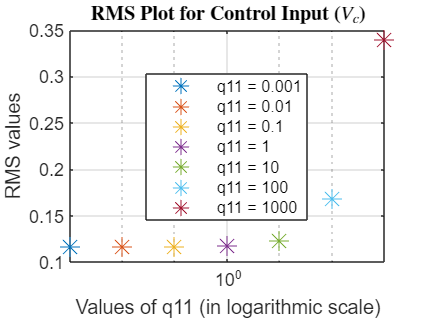

hold off
legend('q11 = 0.001','q11 = 0.01','q11 = 0.1','q11 = 1','q11 = 10','q11 = 100','q11 = 1000', location='best')

#### Choice of q11 and the respective eigenvalues of the closed-loop system 

Looking at the RMS plots above, choosing q11=100 seems to be the right choice as it shows a good trade-off between the transitions of position and the required control input. 

% Eigen values of the closed-loop system when q11=100
x0 = [0.1; 0; 0]';
Q = [100, 0, 0; 
     0, 0, 0;
     0, 0, 0];
K = lqr(A, B, Q, R);
display('Eigen values of closed-loop system when q11=100')

Eigen values of closed-loop system when q11=100


eig(A-B*K) % for q11 = 100

ans = 	1.0e+02 *

  -3.6637 + 4.1017i
  -3.6637 - 4.1017i
  -6.5224 + 0.0000i


### **(d) Comparision between RMS plots when q11=100 and penalizing velocity(xdot)**

tspan = 0:0.0005:0.1; % time period is 0.1 seconds
x0 = [0.1; 0; 0]';
Q = [100, 0, 0; 
     0, 0, 0;
     0, 0, 0];
q22 = [0.01,0.1,1,10,100];

#### RMS plot for position

for i = 1:length(q22)
    Q(2,2) = q22(i);
    K = lqr(A, B, Q, R); % Control gain for different penalties on velocity
    sys = ss(A-B*K,B,C,D); % closed loop-system
    [y, tspan, x] = initial(sys, x0, tspan);
    figure(7)
    rms_pos = rms(y(:,1));
    semilogx(q11(i),rms_pos,'*', 'MarkerSize',10);
    title('\textbf{RMS Plot for Position}', 'Interpreter','latex');
    xlabel('Values of q22 (in logarithmic scale)');
    ylabel('RMS values');
    fprintf('RMS value for position when q22 is %0.2f = %0.2f \n',q22(i),rms_pos);
    hold on
    grid
end 

RMS value for position when q22 is 0.01 = 0.03 
RMS value for position when q22 is 0.10 = 0.04 
RMS value for position when q22 is 1.00 = 0.07 
RMS value for position when q22 is 10.00 = 0.09 
RMS value for position when q22 is 100.00 = 0.10 


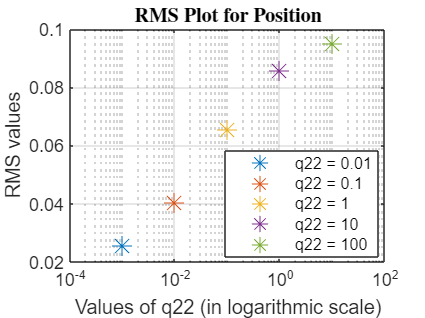

hold off
legend('q22 = 0.01','q22 = 0.1','q22 = 1','q22 = 10','q22 = 100', location='best')

#### RMS plot for velocity (xdot)

for i = 1:length(q22)
    Q(2,2) = q22(i);
    K = lqr(A, B, Q, R); % Control gain for different penalties on velocity
    sys = ss(A-B*K,B,C,D); % closed loop-system
    [y, tspan, x] = initial(sys, x0, tspan);
    figure(8)
    rms_vel = rms(y(:,2));
    semilogx(q22(i),rms_vel,'*', 'MarkerSize',10);
    title('\textbf{RMS Plot for Velocity}', 'Interpreter','latex');
    xlabel('Values of q22 (in logarithmic scale)');
    ylabel('RMS values');
    fprintf('RMS value for velocity when q22 is %0.2f = %0.2f \n',q22(i),rms_vel);
    hold on
    grid
end 

RMS value for velocity when q22 is 0.01 = 2.21 
RMS value for velocity when q22 is 0.10 = 1.28 
RMS value for velocity when q22 is 1.00 = 0.67 
RMS value for velocity when q22 is 10.00 = 0.28 
RMS value for velocity when q22 is 100.00 = 0.10 


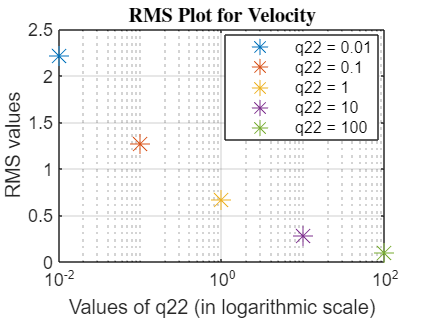

hold off
legend('q22 = 0.01','q22 = 0.1','q22 = 1','q22 = 10','q22 = 100', location='best')

#### RMS plot for current (Ic)

for i = 1:length(q22)
    Q(2,2) = q22(i);
    K = lqr(A, B, Q, R); % Control gain for different penalties on velocity
    sys = ss(A-B*K,B,C,D); % closed loop-system
    [y, tspan, x] = initial(sys, x0, tspan);
    figure(9)
    rms_cur = rms(y(:,2));
    semilogx(q22(i),rms_cur,'*', 'MarkerSize',10);
    title('\textbf{RMS Plot for Current}', 'Interpreter','latex');
    xlabel('Values of q22 (in logarithmic scale)');
    ylabel('RMS values');
    fprintf('RMS value for current when q22 is %0.2f = %0.2f \n',q22(i),rms_cur);
    hold on
    grid
end 

RMS value for current when q22 is 0.01 = 2.21 
RMS value for current when q22 is 0.10 = 1.28 
RMS value for current when q22 is 1.00 = 0.67 
RMS value for current when q22 is 10.00 = 0.28 
RMS value for current when q22 is 100.00 = 0.10 


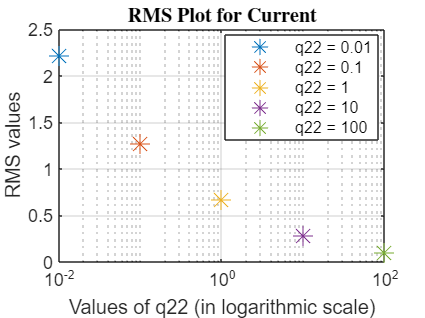

hold off
legend('q22 = 0.01','q22 = 0.1','q22 = 1','q22 = 10','q22 = 100', location='best')

#### RMS plot for control input (Vc)

for i = 1:length(q22)
    Q(2,2) = q22(i);
    K = lqr(A, B, Q, R);
    sys = ss(A-B*K,B,C,D); % closed loop-system
    [y, tspan, x] = initial(sys, x0, tspan);
    u = - (K*x')';
    figure(10)
    rms_u = rms(u);
    semilogx(q22(i),rms_u,'*', 'MarkerSize',10);
    title('\textbf{RMS Plot for Control Input (${V_c}$)}', 'Interpreter','latex');
    xlabel('Values of q22 (in logarithmic scale)');
    ylabel('RMS values');
    fprintf('RMS value of control input when q22 is %0.2f = %0.2f \n',q22(i),rms_u);
    hold on
    grid
end 

RMS value of control input when q22 is 0.01 = 0.17 
RMS value of control input when q22 is 0.10 = 0.22 
RMS value of control input when q22 is 1.00 = 0.33 
RMS value of control input when q22 is 10.00 = 0.49 
RMS value of control input when q22 is 100.00 = 0.75 


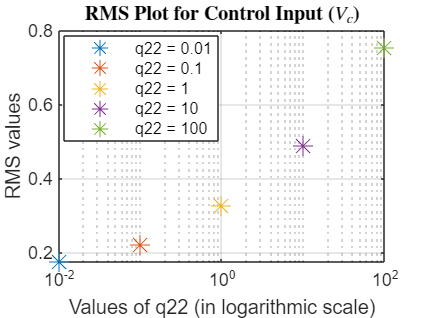

hold off
legend('q22 = 0.01','q22 = 0.1','q22 = 1','q22 = 10','q22 = 100', location='best')

#### Comments on effects of changing q22

From the RMS plots above it can be inferred that as the penalty on velocity (i.e. value of q22) increases the rms value for velocity decreases implying that the state decays faster towards zero.

###  **(e) Optimal feedback controller for system with augmented integrator**

clc;
clear;
A = [0, 1, 0;
     8.75*10^4, 0, 7*10^4;
     0, -1.25, -597.82];
B = [0;
     0;
     271.74];
n = length(A);
C = [1 0 0];
D = 0;
Q = eye(3);
r = [1];

% Augmented matrices
Aa = [A, zeros(3,1); C, 0];
Ba = [B ; 0];
Ca = [C, 0];
sys = ss(Aa, Ba, Ca, D);

% Penalty matrix for states 
Qa = [Q, zeros(3,1); zeros(1,3), 8];

% Checking for controllability
rank(ctrb(Aa,Ba)) % the rank is equal to the number of states, hence controllable

ans = 4

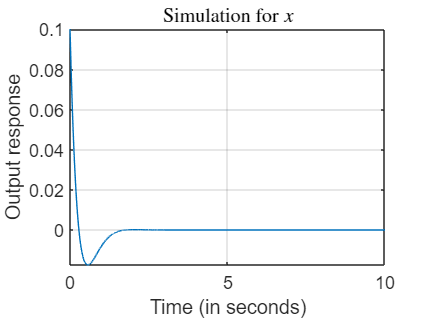


% Calculating gain matrix using lqr
[K,S,e] = lqr(Aa,Ba,Qa,r);

% Adding 0.05 constant drift to the input matrix
sys = ss(Aa-Ba*K,Ba*0.05,Ca,D); % closed-loop system

tspan = 0:0.0005:10; % time period is 10 seconds
x0 = [0.1; 0; 0; 0]';
[y, tspan, x] = initial(sys, x0, tspan);

plot(tspan,y(:,1))
title('Simulation for \textbf{${x}$}','Interpreter','latex');
xlabel('Time (in seconds)');
ylabel('Output response');
grid

In the plot, we can see that position state converges to zero after around 5 seconds. 